clear;
clc;

Dsn=3.3e-14;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=5e-6;

epssn=1-0.39-0.0168;
epssp=1-0.28-0.0429;

Ln=80e-6;
Ls=20e-6;
Lp=71.5e-6;

Lsum=Ln+Ls+Lp;

cs0neg=31542*0.965;
cs0pos=49195*0.239;

csmaxneg=31542;
csmaxpos=49195;

A=0.0784;
Rohm=6e-3;

F=96485.33289;

Qn=A*Ln*epssn*csmaxneg*F/3600;  %Ah
Qp=A*Lp*epssp*csmaxpos*F/3600;  %Ah

soc0n=cs0neg/csmaxneg;
soc0p=cs0pos/csmaxpos;

time=3600;

I=-2.8*ones(time,1);

Rsn_matrix=linspace(12.5e-6,12.5e-6/1.2,time);
Rsp_matrix=linspace(Rsp,Rsp*1.05,time);

Jn_matrix=I*Rsn_matrix/3/epssn/F/A/Ln;
Jp_matrix=-I*Rsp_matrix/3/epssp/F/A/Lp;

Jn=I*Rsn/3/epssn/F/A/Ln;
Jp=-I*Rsp/3/epssp/F/A/Lp;

% socn=soc0n+cumsum(I/3600/Qn);
% socp=soc0p-cumsum(I/3600/Qp);

for i=1:length(Jn)
    FOMe_matrix(:,i)=fom(Rsn_matrix(i),Dsn,Jn_matrix);
end

FOMen=fom(Rsn,Dsn,Jn);
FOMe_stressn=diag(FOMe_matrix);

for i=1:length(Jn)
    FOMe_matrix(:,i)=fom(Rsp_matrix(i),Dsp,Jp_matrix);
end

FOMep=fom(Rsp,Dsp,Jp);
FOMe_stressp=diag(FOMe_matrix);


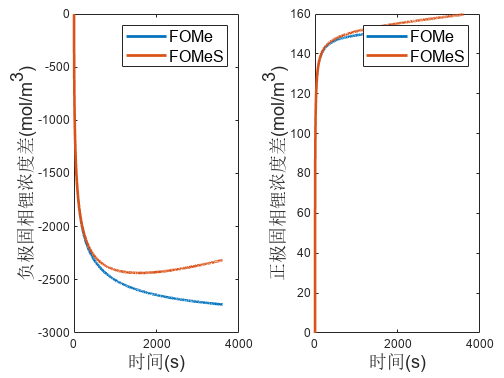

figure(1);
clf;
tiledlayout(1,2,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(FOMen,'LineWidth',2);
hold on;
plot(FOMe_stressn,'LineWidth',2);
legend('FOMe','FOMeS',"FontSize",12);
xlabel('时间(s)',"FontSize",14);
ylabel('负极固相锂浓度差(mol/m^3)',"FontSize",14);
nexttile;
plot(FOMep,'LineWidth',2);
hold on;
plot(FOMe_stressp,'LineWidth',2);
legend('FOMe','FOMeS',"FontSize",12);
xlabel('时间(s)',"FontSize",14);
ylabel('正极固相锂浓度差(mol/m^3)',"FontSize",14);

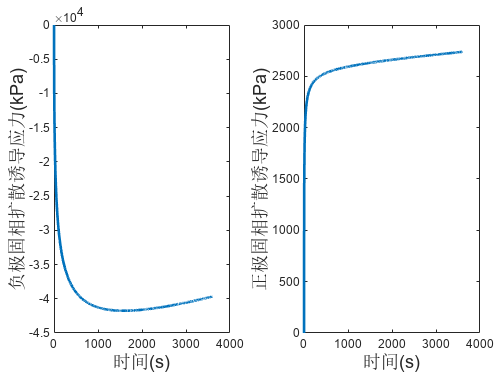

omega_n=3.6e-6;
Young_n=15e6;
poisson_n=0.3;

omega_p=3.6e-6;
Young_p=15e6;
poisson_p=0.3;

stressn=2*Young_n*omega_n/9/(1-poisson_n)*FOMe_stressn;
stressp=2*Young_p*omega_p/9/(1-poisson_p)*FOMe_stressp;

figure(2);
clf;
tiledlayout(1,2,'TileSpacing','Compact','Padding','Compact');
nexttile
plot(stressn,'LineWidth',2);
xlabel('时间(s)',"FontSize",14);
ylabel('负极固相扩散诱导应力(kPa)',"FontSize",14)
nexttile
plot(stressp,'LineWidth',2);
xlabel('时间(s)',"FontSize",14);
ylabel('正极固相扩散诱导应力(kPa)',"FontSize",14)